## Variables tuning

In this section there is the code configuration.

It is possible to setup what to print and the pretrained networks (AlexNet, ResNet and VGG16). 

%%% PRINT VARIABLES %%%
printTrainingSet = 0; % Print random images of the training set
printTestSet = 0; % Print random images of the predicted set
printConfMatr = 1; % Print the confusion matrix

%%% NETWORK SELECTION %%%
% network = "alexnet"; % Uncomment to use alexnet
% network = "resnet"; % Uncomment to use resnet18
network = "vgg"; % Uncomment to use vgg16

## Load Data

Load the training and test set as an image datastore. `imageDatastore` automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore lets you store large image data, including data that does not fit in memory. 

imdsTrain = imageDatastore('TrainingSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('TestSet','IncludeSubfolders',true,'LabelSource','foldernames');
numTrainImages = numel(imdsTrain.Labels);

### Print some images of the training set

In this section if the previous variable is true the code prints random training set images.

if printTrainingSet == 1
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i));
        imshow(I)
    end
end

## Load pretrained Network

Load the pretrained network based on the choice in the variable tuning

tic;
if network == "alexnet"
    net = alexnet;
elseif network == "resnet"
    net = resnet18;
else
    net = vgg16;
end

## Resize the images

The networks require different input size, in this section the image will be resized to fit the first input layer. To automatically resize the training and test images before they are input to the network, create augmented image datastores, specify the desired image size, and use these datastores as input arguments to `activations`.

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

## Select the activation layer for the feature extraction and extract the features

The network constructs a hierarchical representation of input images. Deeper layers contain higher-level features, constructed using the lower-level features of earlier layers. To get the feature representations of the training and test images, the program will use `activations` on different layers depending on the network used. In our case for **alexnet** is **fc7**, for **resnet18** is **pool5** and for **vgg16** is **fc7**. This parameter can be changed. Basically the code is extracting the feature from the layer before the layer that actually classify the things.

if network == "resnet"
    layer = 'pool5';
else
    layer = 'fc7';
end
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');
featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows');
YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;

## Classification

This section use linears svm to perform the classification. In the first rows there's the conversion of the data to the one compatible to liblinear. Next the code trains the model passing the labels and the features. After it performs the prediction using the labels and the features of the test set and the model generated before. At the end it computes the accuracy.

YTrain = double(YTrain(:,1)) -1;
YTest = double(YTest(:,1)) -1;
featuresTrain = sparse(double(featuresTrain));
featuresTest = sparse(double(featuresTest));
model = train(YTrain, featuresTrain, '-s 2');

init f 1.026e+004 |g| 3.644e+006
iter  1 f 1.042e+003 |g| 1.544e+005 CG   2 step_size 1.00e+000 
iter  2 f 6.471e+002 |g| 1.868e+005 CG   7 step_size 1.00e+000 
iter  3 f 3.965e+002 |g| 1.029e+005 CG  10 step_size 1.00e+000 
iter  4 f 2.356e+002 |g| 6.038e+004 CG  10 step_size 1.00e+000 
iter  5 f 1.361e+002 |g| 3.224e+004 CG  10 step_size 1.00e+000 
iter  6 f 7.563e+001 |g| 1.915e+004 CG  10 step_size 1.00e+000 
iter  7 f 6.491e+001 |g| 4.499e+003 CG   5 step_size 1.00e+000 
iter  8 f 3.254e+001 |g| 2.135e+003 CG  10 step_size 1.00e+000 
iter  9 f 1.213e+001 |g| 6.510e+003 CG  18 step_size 1.00e+000 
iter 10 f 1.065e+001 |g| 9.863e+002 CG   2 step_size 1.00e+000 
iter 11 f 7.916e+000 |g| 1.659e+003 CG  11 step_size 1.00e+000 
iter 12 f 6.722e+000 |g| 2.834e+003 CG  10 step_size 1.00e+000 
iter 13 f 4.897e+000 |g| 3.140e+002 CG  10 step_size 1.00e+000 
init f 1.026e+004 |g| 3.667e+006
iter  1 f 7.724e+002 |g| 1.755e+005 CG   2 step_size 1.00e+000 
iter  2 f 4.158e+002 |g| 1.562e+005 CG

YPred = predict(YTest, featuresTest, model);

Accuracy = 92.3251% (2863/3101)


## Show images

This portion of code shows 12 random images of the test set. For each of them it shows the number of the image, the prediction of the model and the correct class.

if printTestSet == 1
    idx = randi([1 3077],1,12);
    % idx = [];
    figure
    for i = 1:numel(idx)
        subplot(3,4,i)
        I = readimage(imdsTest,idx(i));
        label = YPred(idx(i));
        corr = YTest(idx(i));
        imshow(I)
        title("#: "+idx(i)+" / Predicted: "+label+" / Correct: "+corr)
    end
end

## Confusion Matrix

Plot the confusion matrix. If it is too small open it on a new figure.

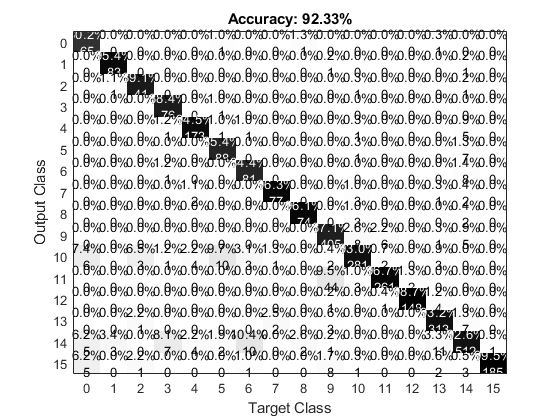

if printConfMatr == 1
    cm = confusionmat(YPred,YTest);
    labels = {0,1,2,3,4,5,6,7,8,9,10,11,12,13,14,15};
    figure
    plotConfMat(cm,labels)
end

## Results

time = toc;
diff = numel(find(YPred~=YTest));
[M,N] = size(YPred);
tp = M-diff;
accuracy = round(mean(YPred == YTest)*100,2);
disp('Accuracy: '+string(accuracy)+"% - Time Elapsed: "+time+" s - True Positive vs Total: "+tp+"/"+M);

Accuracy: 92.33% - Time Elapsed: 1527.7284 s - True Positive vs Total: 2863/3101
